clear
clc
close all

% Start and Goal orientations
theta_start = [0;0];
theta_goal = [1;1];

% Initial trajectory variables
n = 2; % No. of joints/ 2-D trajectory
k = 15; % No. of waypoints

% Obstacles 1 and 2 parameters
% First obstacle's radius and center
r1 = 0.3;
center1 = [0.5;0.3];

% Second obstacle's radius and center
r2 = 0.2; 
center2 = [0.5;0.7];

xi_0 = zeros(n, k); % Initial trajectory

xi_0_vec = reshape(xi_0, [],1); % Reshape for the need of optimization

% Equality constraints for start and goal positions
A = [eye(n), zeros(n,n*(k-1)) ;...
 zeros(n,n*(k-1)), eye(n) ];
B = [theta_start;theta_goal];

% Nonlinear optimization
options = optimoptions('fmincon','Display','iter',...
 'Algorithm','sqp','MaxFunctionEvaluations',1e5);

xi_star_vec = fmincon(@(xi) cost(xi), xi_0_vec, ...
 [], [], A, B, [], [], [], options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          31    0.000000e+00     1.000e+00     1.000e+00     0.000e+00     2.980e-08  
    1          63    9.800000e-01     3.000e-01     7.000e-01     9.899e-01     1.400e+00  
    2          98    8.002409e-01     2.280e-01     2.401e-01     2.482e-01     9.038e-01  
    3         137    7.199803e-01     2.148e-01     5.765e-02     9.956e-02     8.320e-01  
    4         182    7.226496e-01     2.134e-01     6.782e-03     1.237e-02     9.556e+00  
    5         217    7.506090e-01     1.621e-01     2.401e-01     2.927e-01     1.365e+00  
    6         249    1.018032e+00     4.864e-02     7.000e-01     4.074e-01     1.564e+00  
    7         280    1.138203e+00     0.000e+00     1.000e+00     3.986e-01     1.730e+00  
    8         312    1.089659e+00     0.000e+00     7.000e-01     2.766e-01     1.

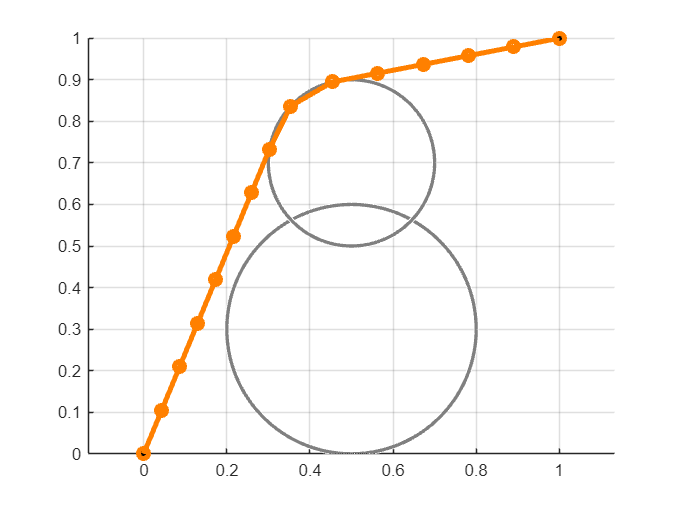

xi_star = reshape(xi_star_vec,2,[]); % final optimized trajectory

% Plot obstacles
figure
grid on
hold on
axis([0, 1, 0, 1])
axis equal
viscircles(center1', r1, 'Color', [0.5, 0.5, 0.5]);
viscircles(center2', r2, 'Color', [0.5, 0.5, 0.5]);
plot(0, 0, 'ko', 'MarkerFaceColor', 'k')
plot(1, 1, 'ko', 'MarkerFaceColor', 'k')
% Plot result
grid on
hold on
axis equal
plot(xi_0(1,:), xi_0(2,:), 'o-', 'Color', [0.3, 0.3, ...
 0.3], 'LineWidth', 3);
plot(xi_star(1,:), xi_star(2,:), 'o-',...
 'Color', [1, 0.5, 0], 'LineWidth', 3);


% Cost function to minimize

function C = cost(xi)
 gamma=20;
 xi = reshape(xi,2,[]);
 C = 0;
 r1 = 0.3;
 center1 = [0.5;0.3];
 r2 = 0.2;
 center2 = [0.5;0.7];
 Urep1 = 0;
 Urep2 = 0;
 for idx = 2:length(xi)
 
 % First obstacle
 if (norm(center1 - xi(:,idx)) <= r1) 
 Urep1 = 0.5*gamma*((1/(norm(center1 - xi(:,idx)))) - (1/r1))^2;
 end
 % Second obstacle
 if (norm(center2 - xi(:,idx)) <= r2) 
 Urep2 = 0.5*gamma*((1/(norm(center2 - xi(:,idx)))) - (1/r2))^2;
 end

 % Total cost
 C = C + norm(xi(:,idx) - xi(:,idx-1))^2 + Urep1 + Urep2;
 end
end